### 1. Adiabatic vs. Isothermal

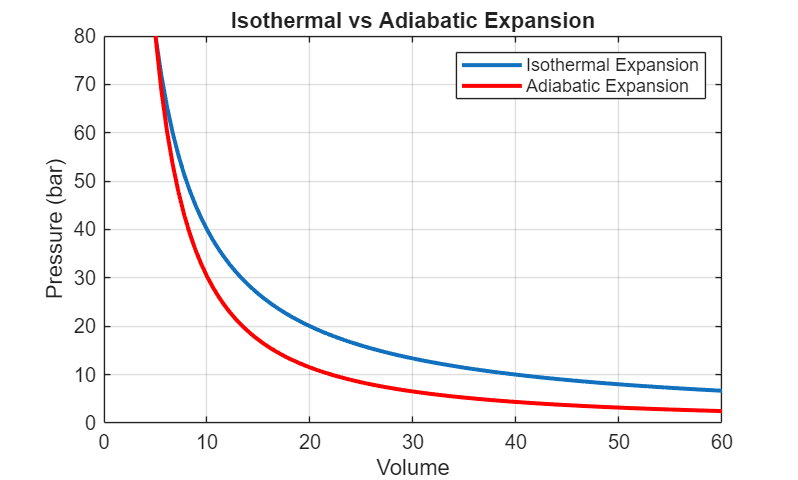

% Simple P-V Diagram: Isothermal vs Adiabatic
clear; clc; close all;

% 1. Parameters
P1 = 80;            % Initial pressure (bar)
V1 = 5;             % Initial volume
V2 = 60;            % Final volume
gamma = 1.4;        % Adiabatic index for air

% 2. Calculate curves
V = linspace(V1, V2, 100);
P_iso = P1 * (V1 ./ V);          % Isothermal (P*V = constant)
P_adi = P1 * (V1 ./ V).^gamma;   % Adiabatic (P*V^gamma = constant)

% 3. Plot
figure;
plot(V, P_iso, '-', 'LineWidth', 2); 
hold on;
plot(V, P_adi, 'r-', 'LineWidth', 2);

% 4. Labels and Legend
xlabel('Volume');
ylabel('Pressure (bar)');
title('Isothermal vs Adiabatic Expansion');
legend('Isothermal Expansion', 'Adiabatic Expansion');
grid on;
hold off;

### Mass flow rate versus temperature

% Plotting the relation: m_dot = 55,661 / T
clear; clc; close all;

% 1. Define the Temperature range (e.g., from 200 K to 1000 K)
T = linspace(200, 1000, 100);

% 2. Calculate the mass flow rate (m_dot)
m_dot = 55661 ./ T;

% 3. Create the plot
figure;
plot(T, m_dot, 'b-', 'LineWidth', 2);

% 4. Formatting and Labels
xlabel('Temperature, T (K)');
ylabel('Mass Flow Rate(kg/s)');
grid on;

### Energy level estimation

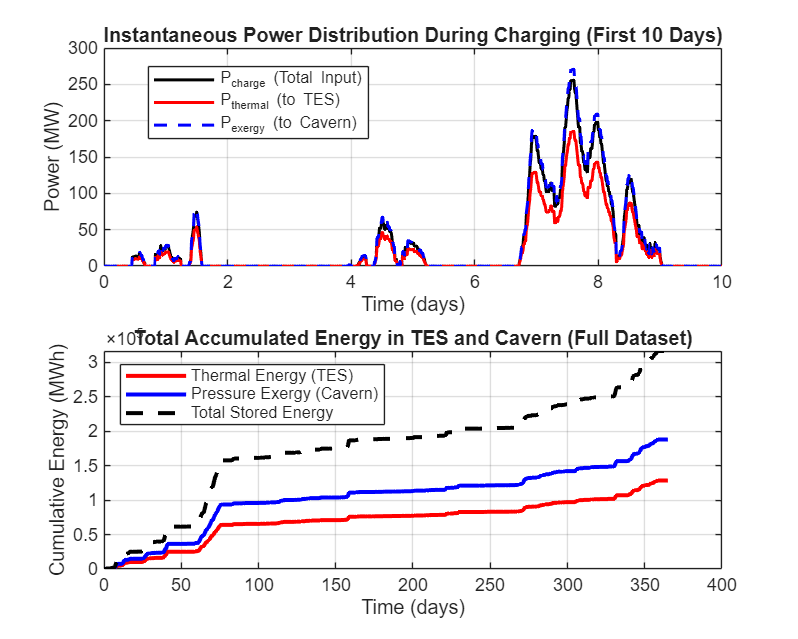

% Energy Accumulation in TES and Cavern Based on Actual Net Power Data
clear; clc; close all;

% ==========================================
% 1. Load Data
% ==========================================
% Load net power data from the CSV file
filename = 'Team38_net_produce.csv';
data = readtable(filename);
t = data.Time_s;                   % Time vector in seconds
P_net = data.Net_Produce_MW * 1e6; % Convert Net power from MW to Watts

% ==========================================
% 2. Physical Constants & System Parameters
% ==========================================
R_air       = 287;       % Specific gas constant of air (J/kg/K)
c_p         = 1005;      % Specific heat at constant pressure (J/kg/K)
n           = 1.05;      % Polytropic index (near-isothermal)
T_in        = 300;       % Ambient inlet temperature (K)
P_atm       = 101325;    % Atmospheric pressure (Pa)
P_store     = 80e5;      % Target storage pressure (80 bar in Pa)

eta_comp    = 0.85;      % Compressor efficiency
eta_thermal = 0.90;      % TES capture efficiency
eta_tran    = 0.98;      % Transmission efficiency
P_limit     = 300e6;      % Assumed maximum charging power limit (300 MW)

% ==========================================
% 3. Calculate Charging Power (P_charge)
% ==========================================
% Implement the piecewise function from the derivation
P_charge = zeros(size(P_net));
for i = 1:length(P_net)
    if P_net(i) >= 0
        % Only charge when there is surplus power (Net >= 0)
        P_charge(i) = eta_tran * min(P_net(i), P_limit);
    else
        P_charge(i) = 0;
    end
end

% ==========================================
% 4. Derived Quantities
% ==========================================
% Compressor outlet temperature
T_out = T_in * (P_store / P_atm)^((n-1)/n);

% Denominator for mass flow rate calculation (constant for fixed P_store)
m_dot_denom = eta_comp * (n/(n-1)) * R_air * T_in * ((P_store/P_atm)^((n-1)/n) - 1);

% ==========================================
% 5. Calculate Thermal Power and Pressure Exergy Rate
% ==========================================
% Mass flow rate (kg/s)
m_dot_charge = P_charge / m_dot_denom;

% Thermal power captured by TES (W)
P_thermal = eta_thermal * (P_charge - m_dot_charge .* c_p .* (T_out - T_in));

% Pressure exergy rate stored in cavern (W)
P_exergy = m_dot_charge .* R_air .* T_in .* log(P_store / P_atm);

% ==========================================
% 6. Integrate to Get Cumulative Energy (J -> MWh)
% ==========================================
% Using cumtrapz to integrate power over time
E_thermal = cumtrapz(t, P_thermal) / 3.6e9;   % Convert Joules to MWh
E_exergy  = cumtrapz(t, P_exergy)  / 3.6e9;   % Convert Joules to MWh
E_total   = E_thermal + E_exergy;

% Convert time from seconds to days for plotting
t_days = t / (24 * 3600);

% ==========================================
% 7. Plotting
% ==========================================
figure('Name', 'I-CAES Energy Accumulation', 'Position', [100, 100, 1000, 800]);

% --- Subplot 1: Power rates over time (Zoomed to first 10 days) ---
subplot(2,1,1);
% Find the index corresponding to 10 days for zooming in
idx_10days = find(t_days <= 10, 1, 'last'); 
if isempty(idx_10days); idx_10days = length(t_days); end

plot(t_days(1:idx_10days), P_charge(1:idx_10days)/1e6, 'k-', 'LineWidth', 1.5); hold on;
plot(t_days(1:idx_10days), P_thermal(1:idx_10days)/1e6, 'r-', 'LineWidth', 1.5);
plot(t_days(1:idx_10days), P_exergy(1:idx_10days)/1e6, 'b--', 'LineWidth', 1.5);
xlabel('Time (days)');
ylabel('Power (MW)');
title('Instantaneous Power Distribution During Charging (First 10 Days)');
legend('P_{charge} (Total Input)', 'P_{thermal} (to TES)', 'P_{exergy} (to Cavern)', 'Location', 'best');
grid on;

% --- Subplot 2: Cumulative energy over the entire year ---
subplot(2,1,2);
plot(t_days, E_thermal, 'r-', 'LineWidth', 2); hold on;
plot(t_days, E_exergy, 'b-', 'LineWidth', 2);
plot(t_days, E_total, 'k--', 'LineWidth', 2);
xlabel('Time (days)');
ylabel('Cumulative Energy (MWh)');
title('Total Accumulated Energy in TES and Cavern (Full Dataset)');
legend('Thermal Energy (TES)', 'Pressure Exergy (Cavern)', 'Total Stored Energy', 'Location', 'northwest');
grid on;